rng(0);
clear;

Consider the dataset provided within the folder “data_fruit” For this question, you cannot use the functions mean(), cov(), and pca() in Matlab. Each datum is an image of size 80 × 80 pixels with 3 color channels red (R), green (G), and blue (B), i.e., a 80 × 80 × 3 array. For PCA, each image should be resized to a vector of length 19200. For visualization, reshape each vector back to a RGB image of size 80 × 80 pixels using the function reshape(), followed by a shift and rescaling of the values into the range [0, 1], followed by displaying the matrix using the function image(). 

imgs = readall(imageDatastore('data_fruit/*.png'));
img_size = size(imgs);

for i = 1:img_size(1)
    imgs{i} = double(reshape(imgs{i}, 19200, 1))/255; 
    
end


• (9 points: 1 + 4 + 4) Similar to the analysis done in previous question, find the mean µ, the covariance matrix C, and the top 4 principle eigenvectors of C. Display the mean and the eigen�vectors as images (side by side, in the same figure); you can use the function subplot(). Find the top 10 eigenvalues, sort them, and plot their values on a graph. Use the function eigs() for efficient computation. 

%mu = sum(image_pro, 2)/img_size(1);
mu = imgs{1};
for i = 2:img_size(1)
    mu = mu + imgs{i};
end
mu = mu/img_size(1);
mu

mu =     0.5027
    0.5100
    0.5162
    0.5069
    0.5130
    0.5238
    0.5211
    0.5203
    0.5262
    0.5360


C = (imgs{1}-mu)*((imgs{1}-mu)');
for i = 2:img_size(1)  
    
    C = C + (imgs{i}-mu)*((imgs{i}-mu)');
end
C = C/img_size(1);
C;

%[Q, D] = eig(C)
[Q, D] = eigs(C, 10);
D = diag(D);    %top 10 eigenvals



Q = Q(:, 1:4)   %only first 4 eigenvecs

Q =     0.0154    0.0005   -0.0057    0.0056
    0.0152    0.0012   -0.0051    0.0060
    0.0151    0.0012   -0.0046    0.0063
    0.0156    0.0002   -0.0053    0.0052
    0.0159    0.0007   -0.0056    0.0050
    0.0159    0.0010   -0.0065    0.0053
    0.0155    0.0006   -0.0079    0.0050
    0.0154    0.0005   -0.0082    0.0049
    0.0159    0.0006   -0.0081    0.0052
    0.0148   -0.0000   -0.0080    0.0055


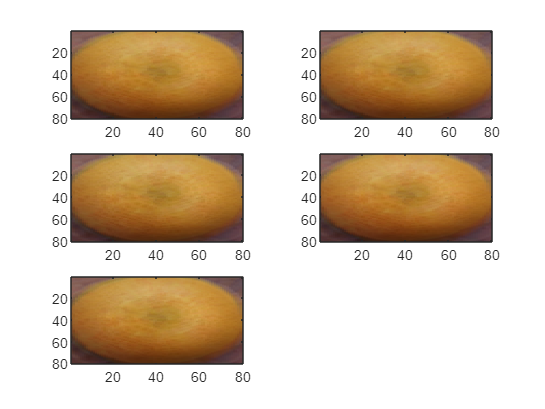

figure
t = tiledlayout(1, 5);
axis equal;
nexttile
imagesc(reshape(mu, 80, 80, 3))

%imagesc(reshape(Q(:, 1) + mu, 80, 80, 3))
for i = 1:4
    nexttile
    imagesc(reshape(Q(:, i) + mu, 80, 80, 3))    
end

D = sort(D);
hold off

%figure(2)
%plot(1:10, D)

• (8 points: 4 + 4) For each fruit image in the dataset, finds its closest representation as a linear combination of the top 4 eigenvectors added to the mean. Use the measure of closeness as the Frobenius norm of the difference. Describe the algorithm used to produce this closest representation in mathematical terms and describe the logic behind your algorithm. Display the original fruit image and its closest representation, as images (side by side, in the same figure). 

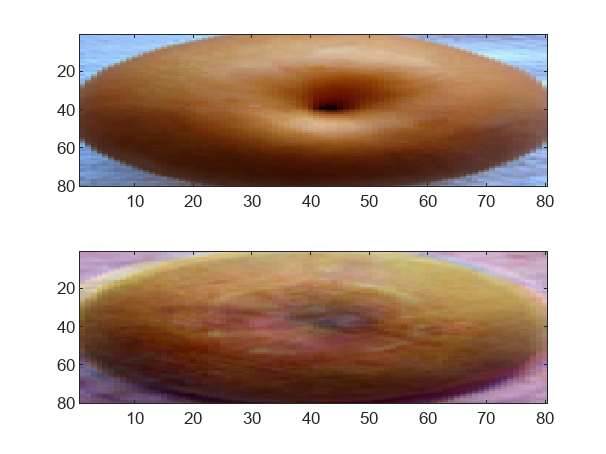

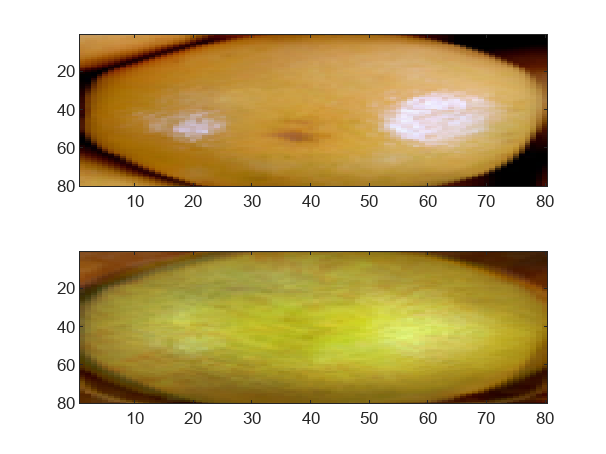

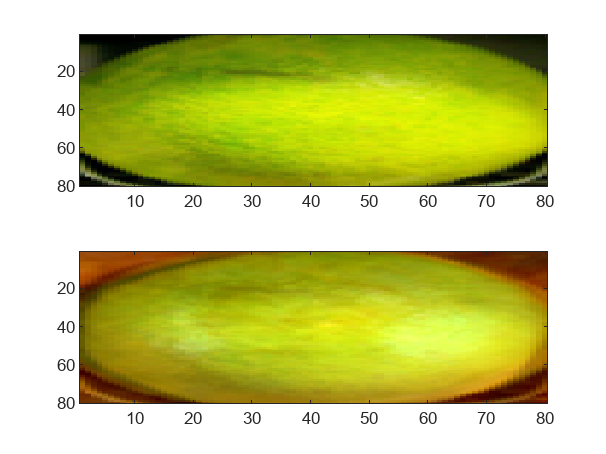

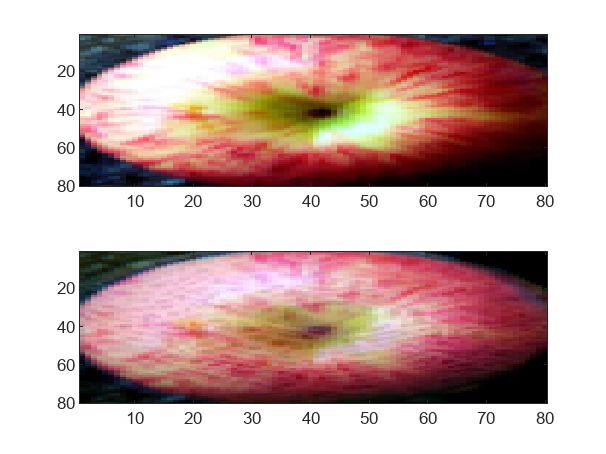

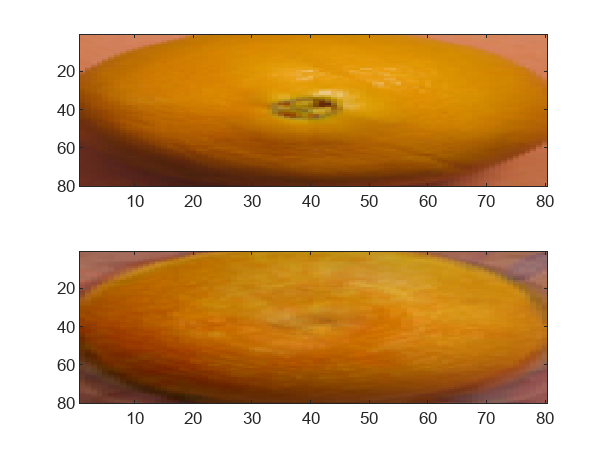

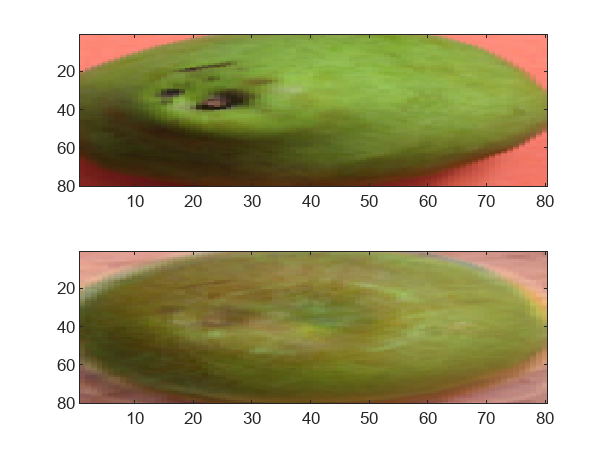

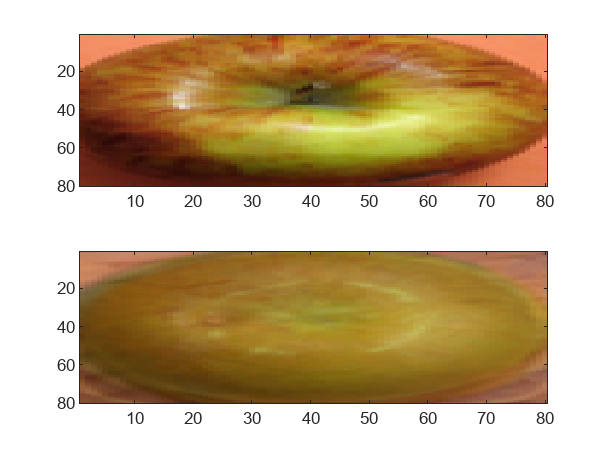

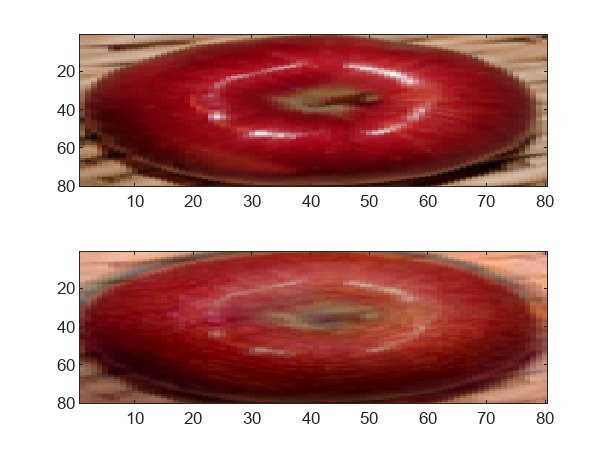

for i = 1:img_size(1)
    pause(0.01)
    figure
    temp_img = imgs{i} - mu;
    components = (temp_img')*Q;
    close_rep_mat = mu + (sum(components*Q', 1))';
    t = tiledlayout(1, 2);
    axis equal;
    nexttile
    imagesc(reshape(imgs{i}, 80, 80, 3));
    nexttile
    imagesc(reshape(close_rep_mat, 80, 80, 3));
    pause(0.01)
end

• (9 points: 3 + 3 + 3) Using all of the top 4 eigenvectors and the mean image, sample random images to generate new images of "fruit". Describe the underlying algorithm clearly in words and including suitable mathematical notation. Display three such images that are distinct from any image in the given the dataset, but are representative of the dataset and can be considered as that of a new / generated fruit.